Lx = 1;
Ly = 2; 
n_x = 21;
n_y = 41;
T_left = 0;
T_right = 0;
T_top = 100;
T_bottom = 0;
tolerance = 0.01;
w_psor = 1.85; %gave least number of iterations for this value of relaxation parameter
w_lsor = 1.25; %gave least number of iterations for this value of relaxation parameter
w_adi = 1.3; % gave least number of iterations for this value of relaxation parameter
del_x = Lx/(n_x-1);
del_y = Ly/(n_y-1);

%Plotting Iterations, CPU time, Computational time and Solution for:
%Point Gauss Seidel Method

[T_array, iteration, cpu_time, comp_time] = Point_GS(Lx, Ly, n_x, n_y, T_left, T_right, T_top, T_bottom, tolerance);

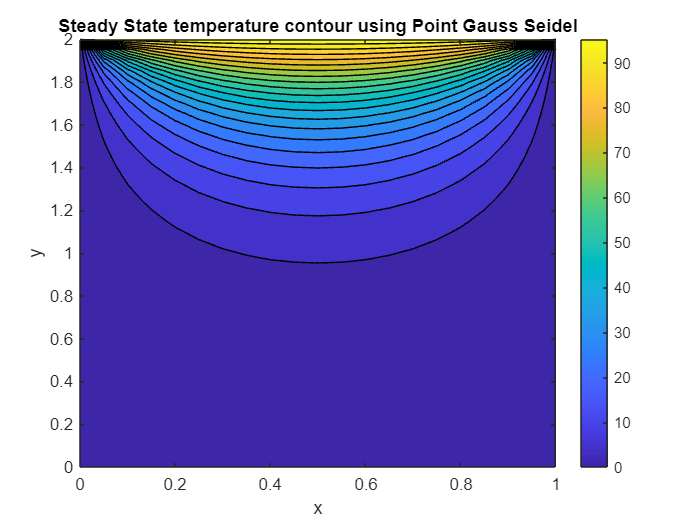

[X,Y] = meshgrid(0:del_x:Lx, 0:del_y:Ly);
contourf(X, Y, T_array, 20, 'LineWidth', 0.05);
colorbar;
xlabel('x');
ylabel('y');
title('Steady State temperature contour using Point Gauss Seidel');
saveas(gcf, 'PGS.png');

% Print the table data
fprintf('Scheme used = %s, Grid size = %d x %d, No. of iterations = %d, CPU Time (s) = %.2f, Total Computational Time (s) = %.2f\n', ...
    "Point Gauss Seidel", n_x, n_y, iteration, cpu_time, comp_time);

Scheme used = Point Gauss Seidel, Grid size = 21 x 41, No. of iterations = 593, CPU Time (s) = 3.87, Total Computational Time (s) = 0.01


%Plotting Iterations, CPU time, Computational time and Solution for:
%Line Gauss Seidel Method

[T_array, iteration, cpu_time, comp_time] = Line_GS(Lx, Ly, n_x, n_y, T_left, T_right, T_top, T_bottom, tolerance);

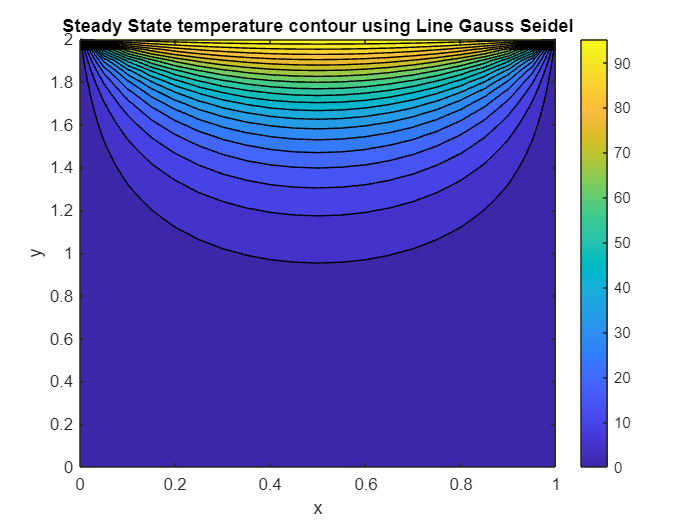

[X,Y] = meshgrid(0:del_x:Lx, 0:del_y:Ly);
contourf(X, Y, T_array, 20, 'LineWidth', 0.05);
colorbar;
xlabel('x');
ylabel('y');
title('Steady State temperature contour using Line Gauss Seidel');
saveas(gcf, 'LGS.png');

% Print the table data
fprintf('Scheme used = %s, Grid size = %d x %d, No. of iterations = %d, CPU Time (s) = %.2f, Total Computational Time (s) = %.2f\n', ...
    "Line Gauss Seidel", n_x, n_y, iteration, cpu_time, comp_time);

Scheme used = Line Gauss Seidel, Grid size = 21 x 41, No. of iterations = 327, CPU Time (s) = 9.22, Total Computational Time (s) = 0.05


%Plotting Iterations, CPU time, Computational time and Solution for:
%PSOR Method

[T_array, iteration, cpu_time, comp_time] = PSOR(Lx, Ly, n_x, n_y, T_left, T_right, T_top, T_bottom, tolerance, w_psor);

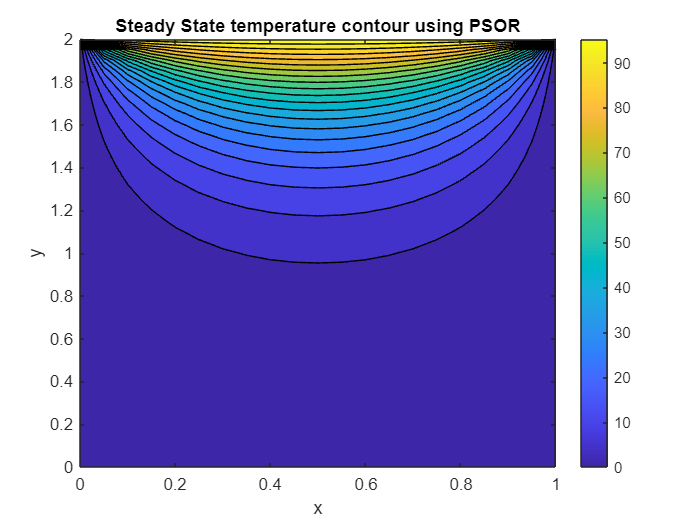

[X,Y] = meshgrid(0:del_x:Lx, 0:del_y:Ly);
contourf(X, Y, T_array, 20, 'LineWidth', 0.05);
colorbar;
xlabel('x');
ylabel('y');
title('Steady State temperature contour using PSOR');
saveas(gcf, 'PSOR_fig.png');

% Print the table data
fprintf('Scheme used = %s, Grid size = %d x %d, No. of iterations = %d, CPU Time (s) = %.2f, Total Computational Time (s) = %.2f\n', ...
    "PSOR", n_x, n_y, iteration, cpu_time, comp_time);

Scheme used = PSOR, Grid size = 21 x 41, No. of iterations = 93, CPU Time (s) = 0.28, Total Computational Time (s) = 0.00


%Plotting Iterations, CPU time, Computational time and Solution for:
%LSOR Method

[T_array, iteration, cpu_time, comp_time] = LSOR(Lx, Ly, n_x, n_y, T_left, T_right, T_top, T_bottom, tolerance, w_lsor);

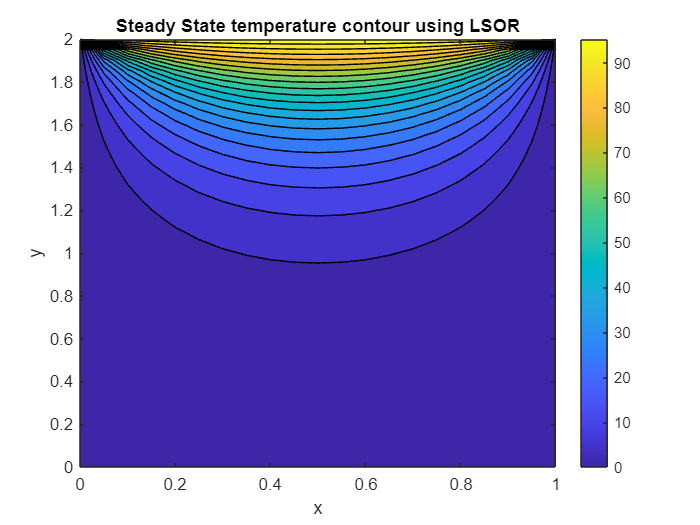

[X,Y] = meshgrid(0:del_x:Lx, 0:del_y:Ly);
contourf(X, Y, T_array, 20, 'LineWidth', 0.05);
colorbar;
xlabel('x');
ylabel('y');
title('Steady State temperature contour using LSOR');
saveas(gcf, 'LSOR_fig.png');

% Print the table data
fprintf('Scheme used = %s, Grid size = %d x %d, No. of iterations = %d, CPU Time (s) = %.2f, Total Computational Time (s) = %.2f\n', ...
    "LSOR", n_x, n_y, iteration, cpu_time, comp_time);

Scheme used = LSOR, Grid size = 21 x 41, No. of iterations = 76, CPU Time (s) = 0.74, Total Computational Time (s) = 0.02


%Plotting Iterations, CPU time, Computational time and Solution for:
%ADI Method

[T_array, iteration, cpu_time, comp_time] = ADI(Lx, Ly, n_x, n_y, T_left, T_right, T_top, T_bottom, tolerance);

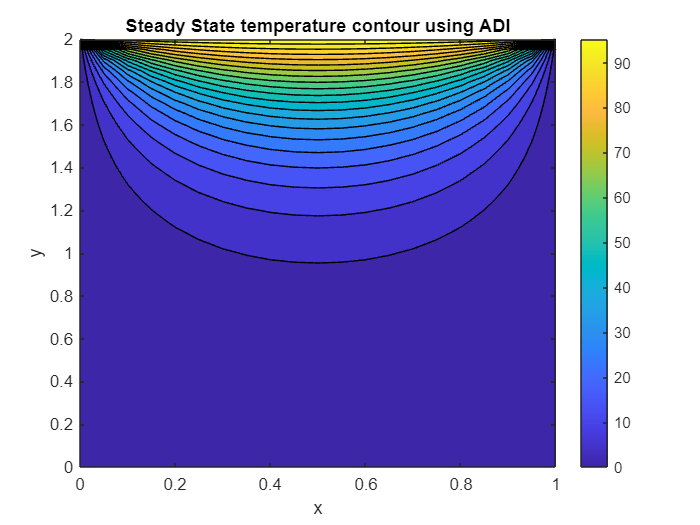

[X,Y] = meshgrid(0:del_x:Lx, 0:del_y:Ly);
contourf(X, Y, T_array, 20, 'LineWidth', 0.05);
colorbar;
xlabel('x');
ylabel('y');
title('Steady State temperature contour using ADI');
saveas(gcf, 'ADI_fig.png');

% Print the table data
fprintf('Scheme used = %s, Grid size = %d x %d, No. of iterations = %d, CPU Time (s) = %.2f, Total Computational Time (s) = %.2f\n', ...
    "ADI", n_x, n_y, iteration, cpu_time, comp_time);

Scheme used = ADI, Grid size = 21 x 41, No. of iterations = 174, CPU Time (s) = 4.17, Total Computational Time (s) = 0.04


%Plotting Iterations, CPU time, Computational time and Solution for:
%ADI Method with relaxation

[T_array, iteration, cpu_time, comp_time] = ADI_relax(Lx, Ly, n_x, n_y, T_left, T_right, T_top, T_bottom, tolerance, w_adi);

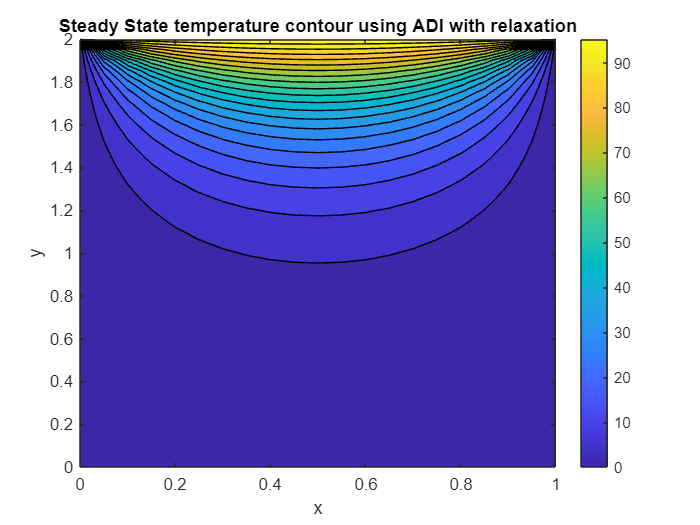

[X,Y] = meshgrid(0:del_x:Lx, 0:del_y:Ly);
contourf(X, Y, T_array, 20, 'LineWidth', 0.05);
colorbar;
xlabel('x');
ylabel('y');
title('Steady State temperature contour using ADI with relaxation');
saveas(gcf, 'ADI_relax_fig.png');

% Print the table data
fprintf('Scheme used = %s, Grid size = %d x %d, w = %f, No. of iterations = %d, CPU Time (s) = %.2f, Total Computational Time (s) = %.2f\n', ...
    "ADI with relaxation", n_x, n_y, w_adi, iteration, cpu_time, comp_time);

Scheme used = ADI with relaxation, Grid size = 21 x 41, w = 1.300000, No. of iterations = 28, CPU Time (s) = 0.55, Total Computational Time (s) = 0.03
